This is a demo file for a Matlab Live Editor file.

You can combine text and code, just like in a Jypiter Notebook - with the only difference being that you have to pay for it...

you can display some cool code:

clear; close all; clc
outcome = 1; V = .5; alpha = .6;
PE = outcome - V

PE = 0.5000

V = V + alpha * PE

V = 0.8000

and you can also run some functions: such as the learning rate

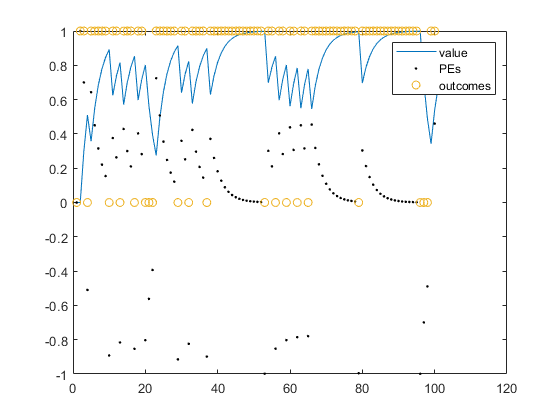

addpath('.\general_functions\')
% 80:20 rewarding outcomes
outcomes = [zeros(20,1); ones(80,1)]; outcomes = outcomes(randperm(length(outcomes)));
% prior at 0
V = 0; 
% learning rate = .3
params = [];
params.alpha = .3;
PE = [];
for t = 1:length(outcomes)
    [V(t+1), PE(t)] = learn_RescWagn(V(t),outcomes(t),params);
end

figure()
plot(V,'DisplayName','value')
hold on
plot(PE,'k.','DisplayName','PEs')
plot(outcomes,'o','DisplayName','outcomes')
legend

or  how does the softmax work?

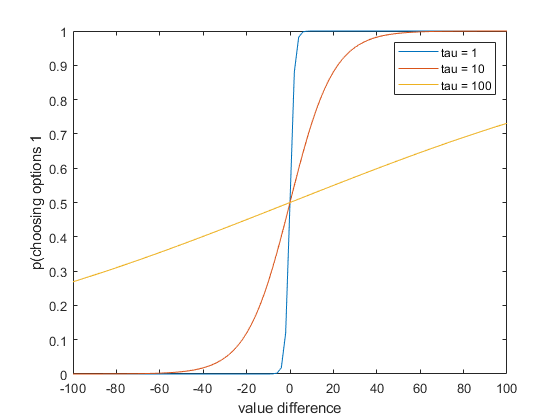

% have choice values between 0 and 100
values = [0:100; 100:-1:0];

% have several different temperatures
taus = [1 10 100];

figure()
for i = 1:length(taus)
    params = []; params.tau = taus(i);
    for v = 1:length(values)
        policy(i,v,:) = softmax(values(:,v),params);
    end
    plot(values(1,:)-values(2,:),squeeze(policy(i,:,1)),'DisplayName',['tau = ' num2str(taus(i))])
    hold on
end
legend
xlabel('value difference')
ylabel('p(choosing options 1')